# **LI-DTI: Linear Interpretable Drug-Target Interaction **

**Warm Start Scenario**

- Output: Calculate and plot of the AUC and AUPR (mean,std) using the AUCDownSample function.

## Initialization 

clear all;

Load all the prediction for get the results

load('../repository/warm_start_10_CVs/our_method/our_method_predictions_10CV_2026.mat');
load('../repository/warm_start_10_CVs/neoDTI/neoDTI_10_cv_predictions.mat');
load('../repository/warm_start_10_CVs/KGE_NFM/KGE_NFM_10_cv_predictions.mat');
load('../repository/warm_start_10_CVs/DTINet/DTInet_10CV_predictions_10_to_1.mat');
load('../repository/warm_start_10_CVs/hampDTI/hampDTI_predictions.mat');

Calculate AUC and AUPR for each model with AUCDownSample function

nfolds = 10;
%     our_method = zeros(ratemax,2);
%     NeoDTI = zeros(ratemax,2);
%     KGE_NFM = zeros(ratemax,2);
%     DTINet = zeros(ratemax,2);
tic
    tmp_our_method = zeros(nfolds,2);
    tmp_NeoDTI = zeros(nfolds,2);
    tmp_KGE_NFM = zeros(nfolds,2);
    tmp_DTINet = zeros(nfolds,2);
    tmp_hampDTI = zeros(nfolds,2);
    for k = 1:10
        AUC_our_method = zeros(nfolds,1);
        AUPR_our_method = zeros(nfolds,1);
        AUC_NeoDTI = zeros(nfolds,1);
        AUPR_NeoDTI = zeros(nfolds,1);
        KGE_NFM_AUC = zeros(nfolds,1);
        KGE_NFM_AUPR = zeros(nfolds,1);
        DTINet_AUC = zeros(nfolds,1);
        DTINet_AUPR = zeros(nfolds,1);
        hampDTI_AUC = zeros(nfolds,1);
        hampDTI_AUPR = zeros(nfolds,1);
        for j = 1:nfolds
            load(['../data/luo_dataset/warm_start_10_CVs/our_method/cv_' int2str(k) '/test' int2str(j) '.mat']);
            [AUC_our_method(j), AUPR_our_method(j), ~,~,~,~] = AUCDownSample(test_fold, our_method_predictions{k}{j});
            [AUC_NeoDTI(j), AUPR_NeoDTI(j), ~,~,~,~] = AUCDownSample(test_fold, neoDTI_predictions{k}{j});
            [KGE_NFM_AUC(j), KGE_NFM_AUPR(j), ~,~,~,~] = AUCDownSample(test_fold, KGE_NFM_predictions{k}{j});
            [DTINet_AUC(j), DTINet_AUPR(j), ~,~,~,~] = AUCDownSample(test_fold, DTINet_predictions_10_1{k}{j});
            [hampDTI_AUC(j), hampDTI_AUPR(j), ~,~,~,~] = AUCDownSample(test_fold, hampDTI_predictions{k}{j});
        end
        tmp_our_method(k,:) = [mean(AUC_our_method),mean(AUPR_our_method)];
        tmp_NeoDTI(k,:) = [mean(AUC_NeoDTI),mean(AUPR_NeoDTI)];
        tmp_KGE_NFM(k,:) = [mean(KGE_NFM_AUC),mean(KGE_NFM_AUPR)];
        tmp_DTINet(k,:) = [mean(DTINet_AUC),mean(DTINet_AUPR)];
        tmp_hampDTI(k,:) = [mean(hampDTI_AUC),mean(hampDTI_AUPR)];
    end

toc

Elapsed time is 2.665161 seconds.


Plot the AUC and AUPR 

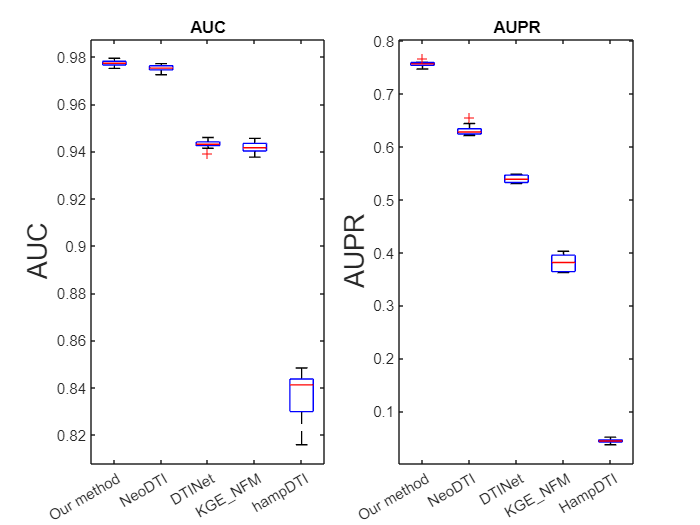

figure;
subplot(1,2,1);
boxplot([tmp_our_method(:,1) tmp_NeoDTI(:,1) tmp_DTINet(:,1) tmp_KGE_NFM(:,1) tmp_hampDTI(:,1)]);
ylabel('AUC', 'FontSize', 16);
set(gca,'xticklabel',{'Our method','NeoDTI','DTINet','KGE_NFM','hampDTI'});
title('AUC');
%ylim([0.95 1]);

subplot(1,2,2);
boxplot([tmp_our_method(:,2) tmp_NeoDTI(:,2) tmp_DTINet(:,2) tmp_KGE_NFM(:,2) tmp_hampDTI(:,2)]);
%xlabel('Unalanced', 'FontSize', 16);
ylabel('AUPR', 'FontSize', 16);
set(gca,'xticklabel',{'Our method','NeoDTI','DTINet','KGE_NFM','HampDTI'});
title('AUPR');

% Can be saved the matrices for plotting in python the results
% wsAUC = [tmp_our_method(:,1) tmp_NeoDTI(:,1) tmp_DTINet(:,1) tmp_KGE_NFM(:,1) tmp_hampDTI(:,1)];
% save("../../repository/paper_data/warm_start_AUC.mat",'wsAUC');
% wsAUPR = [tmp_our_method(:,2) tmp_NeoDTI(:,2) tmp_DTINet(:,2) tmp_KGE_NFM(:,2) tmp_hampDTI(:,2)];
% save("../../repository/paper_data/warm_start_AUPR.mat",'wsAUPR');

% wsAUC = [tmp_our_method(:,1) tmp_NeoDTI(:,1) tmp_DTINet(:,1) tmp_KGE_NFM(:,1) tmp_hampDTI(:,1)];
% wsAUPR = [tmp_our_method(:,2) tmp_NeoDTI(:,2) tmp_DTINet(:,2) tmp_KGE_NFM(:,2) tmp_hampDTI(:,2)];

% array2table([mean(wsAUC)' std(wsAUC)' mean(wsAUPR)' std(wsAUPR)'])
% wsAUPR = [tmp_our_method(:,2) tmp_NeoDTI(:,2) tmp_DTINet(:,2) tmp_KGE_NFM(:,2) tmp_hampDTI(:,2)];
% save("../../repository/paper_data/warm_start_AUPR.mat",'wsAUPR');